# Calculating fluxes of specific reactions using different carbon sources

## Normalizing fluxes by C mmol

load('iGC1310');
model = iGC1310;

%Ammonium uptake fixed to -1
model = changeRxnBounds(model, {'EX_nh4_e','EX_succ_e'}, [-1,0], 'l');


lbs = 0:0.8:12;
nLbs = length(lbs);
nRxns = length(model.rxns);
fluxMatrix   = zeros(nRxns, nLbs);
growth_rates = zeros(1, nLbs);

carbonSources= {
'EX_co2_e'
'EX_met__L_e'
'EX_metsox_S__L_e'
'EX_acgam_e'
'EX_cellb_e'
'EX_crn_e'
'EX_hxan_e'
'EX_ile__L_e'
'EX_chol_e'
'EX_lac__L_e'
'EX_leu__L_e'
'EX_glcn_e'
'EX_orn_e'
'EX_gln__L_e'
'EX_pro__L_e'
'EX_glyc_e'
'EX_man_e'
'EX_ade_e'
'EX_4abut_e'
'EX_ac_e'
'EX_akg_e'
'EX_ala__L_e'
'EX_arg__L_e'
'EX_asp__L_e'
'EX_pyr_e'
'EX_succ_e'
'EX_thymd_e'
'EX_rib__D_e'
'EX_tyr__L_e'
'EX_cytd_e'
'EX_dcyt_e'
'EX_fum_e'
'EX_sbt__D_e'
'EX_glu__L_e'
'EX_gua_e'
'EX_btn_e'
'EX_ptrc_e'
'EX_spmd_e'
'EX_thym_e'
'EX_xtsn_e'
'EX_glc__D_e'
'EX_alltn_e'
'EX_ura_e'
'EX_val__L_e'
'EX_xan_e'
'EX_dgsn_e'
'EX_arab__L_e'
'EX_fru_e'
'EX_gal_e'
'EX_xyl__D_e'
'EX_duri_e'
'EX_for_e'
'EX_gly_e'
'EX_lys__L_e'
'EX_ser__L_e'
'EX_thm_e'
'EX_trp__L_e'
'EX_din_e'
'EX_fmn_e'
'EX_gthox_e'
'EX_tmao_e'
'EX_acald_e'
'EX_melib_e'
'EX_sucr_e'
'EX_tre_e'
'EX_hdcea_e'
'EX_lac__D_e'
'EX_ttdcea_e'
'EX_gthrd_e'
'EX_26dap__M_e'
'EX_acnam_e'
'EX_amp_e'
'EX_dha_e'
'EX_fuc__L_e'
'EX_met__D_e'
'EX_tartr__L_e'
'EX_taur_e'
'EX_maltpt_e'
'EX_glyald_e'
'EX_glcur_e'
'EX_nmn_e'
'EX_urea_e'
'EX_f6p_e'
'EX_rmn_e'
'EX_ttdca_e'
'EX_glyclt_e'
'EX_g6p_e'
'EX_2ddglcn_e'
'EX_mmet_e'
'EX_galct__D_e'
'EX_idon__L_e'
'EX_indole_e'
'EX_3hcinnm_e'
'EX_acac_e'
'EX_acmana_e'
'EX_galur_e'
'EX_adn_e'
'EX_ins_e'
'EX_glyc3p_e'
'EX_but_e'
'EX_lcts_e'
'EX_ocdca_e'
'EX_cbl1_e'
'EX_nac_e'
'EX_dad_2_e'
'EX_ser__D_e'
'EX_gam6p_e'
'EX_15dap_e'
'EX_ocdcea_e'
'EX_cynt_e'
'EX_galctn__D_e'
'EX_glyb_e'
'EX_ascb__L_e'
'EX_ala_B_e'
'EX_agm_e'
'EX_minohp_e'
'EX_hxa_e'
'EX_lyx__L_e'
'EX_acmum_e'
'EX_dca_e'
'EX_all__D_e'
'EX_octa_e'
'EX_gbbtn_e'
'EX_xylu__L_e'
'EX_gdp_e'
'EX_gtp_e'
'EX_tma_e'
'EX_fruur_e'
'EX_malttr_e'
'EX_cbi_e'
'EX_arbtn_fe3_e'
'EX_cpgn_e'
'EX_ch4_e'
'EX_adocbl_e'
'EX_ppa_e'
'EX_fad_e'
'EX_meoh_e'
'EX_fe3dcit_e'
'EX_fe3hox_e'
'EX_fecrm_e'
'EX_feenter_e'
'EX_feoxam_e'
'EX_3amp_e'
'EX_3gmp_e'
'EX_3ump_e'
'EX_glyc__R_e'
'EX_eca4colipa_e'
'EX_mal__D_e'
'EX_pheme_e'
'EX_mso3_e'
'EX_23camp_e'
'EX_23cgmp_e'
'EX_23cump_e'
'EX_sulfac_e'
'EX_butso3_e'
'EX_ethso3_e'
'EX_tym_e'
'EX_imp_e'
'EX_fe3hox_un_e'
'EX_23dappa_e'
'EX_enter_e'
'EX_fecrm_un_e'
'EX_cgly_e'
'EX_chtbs_e'
'EX_gmp_e'
'EX_ump_e'
'EX_pydam_e'
'EX_frulys_e'
'EX_enlipa_e'
'EX_hacolipa_e'
'EX_etha_e'
'EX_hdca_e'
'EX_glcr_e'
'EX_ala__D_e'
'EX_mnl_e'
'EX_malt_e'
'EX_pnto__R_e'
'EX_asn__L_e'
'EX_cit_e'
'EX_mal__L_e'
'EX_gam_e'
'EX_inost_e'
'EX_phe__L_e'
'EX_thr__L_e'
'EX_uri_e'
'EX_ddca_e'
'EX_r5p_e'
'EX_glyc2p_e'
'EX_halipa_e'
'EX_cmp_e'
'EX_malthx_e'
'EX_csn_e'
'EX_etoh_e'
'EX_g3pe_e'
'EX_pacald_e'
'EX_his__L_e'
'EX_dmso_e'
'EX_12ppd__S_e'
'EX_pppn_e'
'EX_acgam1p_e'
'EX_galt_e'
'EX_glcur1p_e'
'EX_thrp_e'
'EX_fald_e'
'EX_pydxn_e'
'EX_acgal_e'
'EX_dms_e'
'EX_acgal1p_e'
'EX_cyan_e'
'EX_tyrp_e'
'EX_uacgam_e'
'EX_udpacgal_e'
'EX_udpg_e'
'EX_udpgal_e'
'EX_udpglcur_e'
'EX_14glucan_e'
'EX_pser__L_e'
'EX_xmp_e'
'EX_damp_e'
'EX_dimp_e'
'EX_isetac_e'
'EX_tcynt_e'
'EX_fe3dhbzs_e'
'EX_feoxam_un_e'
'EX_g3pc_e'
'EX_g3pg_e'
'EX_g3pi_e'
'EX_g3ps_e'
'EX_peamn_e'
'EX_34dhpac_e'
'EX_cys__L_e'
'EX_gsn_e'
'EX_orot_e'
'EX_manglyc_e'
'EX_metsox_R__L_e'
'EX_dgmp_e'
'EX_4hoxpacd_e'
'EX_3hpppn_e'
'EX_man6p_e'
'EX_maltttr_e'
'EX_alaala_e'
'EX_dtmp_e'
'EX_lipoate_e'
'EX_pydx_e'
'EX_g1p_e'
'EX_progly_e'
'EX_gal_bD_e'
'EX_dump_e'
'EX_12ppd__R_e'
'EX_gal1p_e'
'EX_dcmp_e'
'EX_23ccmp_e'
'EX_3cmp_e'
'EX_urate_e'
'EX_skm_e'
'EX_cpgn_un_e'
'EX_cys__D_e'
'EX_acser_e'
'EX_arbtn_e'
'EX_dopa_e'
'EX_tartr__D_e'
'EX_galctn__L_e'
'EX_hom__L_e'
'EX_crn__D_e'
'EX_LalaDgluMdapDala_e'
'EX_5dglcn_e'
'EX_LalaDgluMdap_e'
'EX_psclys_e'
'EX_anhgm_e'
'EX_ppal_e'
'EX_LalaDglu_e'
'EX_5mtr_e'
'EX_LalaLglu_e'
'EX_ttrcyc_e'
'EX_mincyc_e'
'EX_arbt_e'
'EX_dxylnt_e'
'EX_mththf_e'
'EX_doxrbcn_e'
'EX_dhps_e'
'EX_fusa_e'
'EX_mepn_e'
'EX_cm_e'
'EX_novbcn_e'
'EX_2dglc_e'
'EX_sq_e'
'EX_4abzglu_e'
'EX_rfamp_e'
'EX_metglcur_e'
'EX_quin_e'
'EX_3hpp_e'
'EX_2obut_e'
'EX_glx_e'
'EX_glycogen_e'
'EX_gg4abut_e'
'EX_4hbz_e'
'EX_oxa_e'
'EX_acglu_e'
'EX_glu__D_e'
'EX_citr__L_e'
'EX_gly_asp__L_e'
'EX_gly_glu__L_e'
'EX_L_alagly_e'
'EX_gly_pro__L_e'
'EX_ala_L_asp__L_e'
'EX_ala_L_gln__L_e'
'EX_ala_L_glu__L_e'
'EX_ala_L_his__L_e'
'EX_ala_L_leu__L_e'
'EX_ala_L_Thr__L_e'
'EX_gly_asn__L_e'
'EX_gly_gln__L_e'
'EX_gly_met__L_e'
'EX_met_L_ala__L_e'};

rxnNames = {'AMO','BIOMASS_core'};

rxnIDs = zeros(size(rxnNames));
for k = 1:numel(rxnNames)
    rxnIDs(k) = findRxnIDs(model, rxnNames{k});
end
model2=model;


for j = 1:length(carbonSources)
    model = model2;
    cs = carbonSources{j};

    % Carbon-normalization factor for this carbon source (nC)
    rxnID_cs  = findRxnIDs(model, cs);
    metIdx_cs = find(model.S(:, rxnID_cs) ~= 0);  % 
    if isempty(metIdx_cs)
        nC = 1;  
    else
        formula_cs = model.metFormulas{metIdx_cs(1)};
        nC = countCarbons(formula_cs);
        if nC == 0 || isnan(nC)
            nC = 1; 
        end
    end

    for i = 1:nLbs
        lb = lbs(i);

        % carbon-equivalent uptake: lb is mmol-C/gDW/h, convert to mmol-met/gDW/h
        model = changeRxnBounds(model, cs, -1*(lb / nC), 'l');

        FBA = optimizeCbModel_gaby(model);

        if isempty(FBA) || ~isfield(FBA,'f') || isnan(FBA.f)
            X = zeros(nRxns,1);
        else
            X = FBA.x;
        end
        fluxMatrix(:, i) = X;
    end

    for n = 1:length(rxnNames)
        rxn_name = rxnNames{n};
        Flux_by_enzyme = fluxMatrix(findRxnIDs(model, rxn_name), :)';
        vname = matlab.lang.makeValidName(rxn_name);
        csn   = matlab.lang.makeValidName(cs);   

        if evalin('base', sprintf('exist(''%s'',''var'')', vname))
            T = evalin('base', vname);        
        else
            T = table();                       
        end

        T.(csn) = Flux_by_enzyme;              
        assignin('base', vname, T);
    end
end




## Eliminating carbon sources not producing growth

cols=BIOMASS_core.Properties.VariableNames;
for i=1:length(cols)
    col=cols{i};
    total_gr=sum(BIOMASS_core.(col));
    if total_gr <= 0
        for j=1:length(rxnNames)
            rxn=rxnNames{j};
            T = evalin('base', rxn);        
            if istable(T) && ismember(col, T.Properties.VariableNames)
                T(:, col) = [];             
                assignin('base', rxn, T);   
            end
        end
        
    end
end


## Plotting clustermaps

@author : slandarer


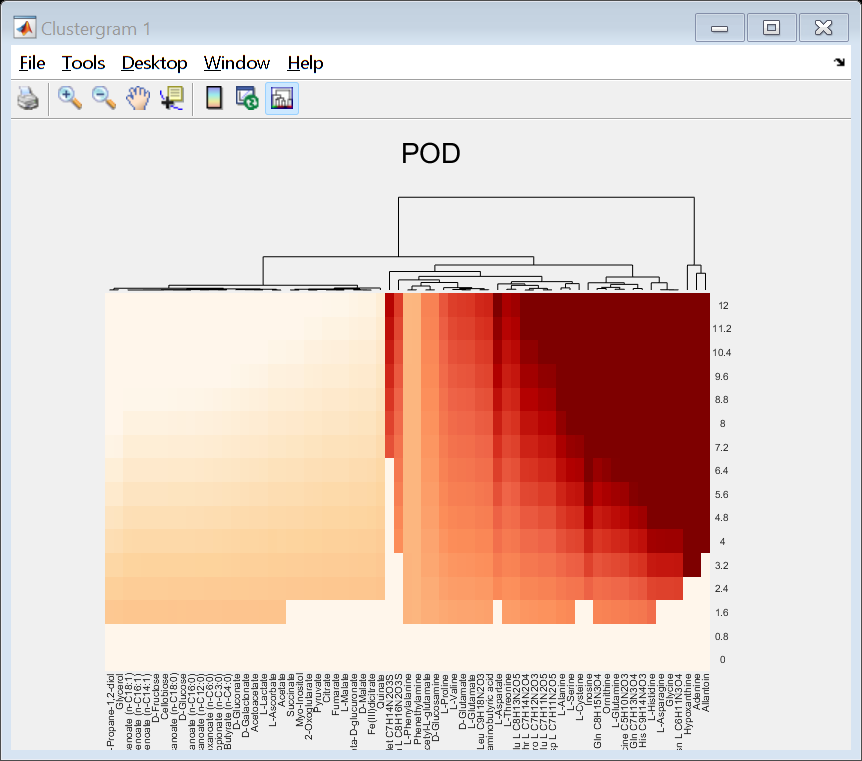

@author : slandarer


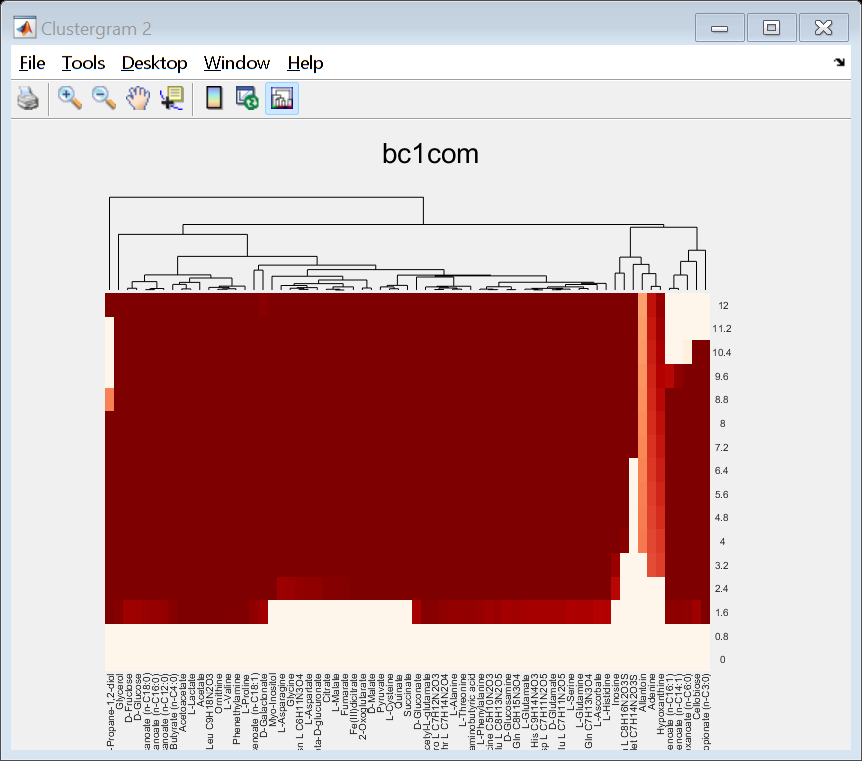

@author : slandarer
@author : slandarer


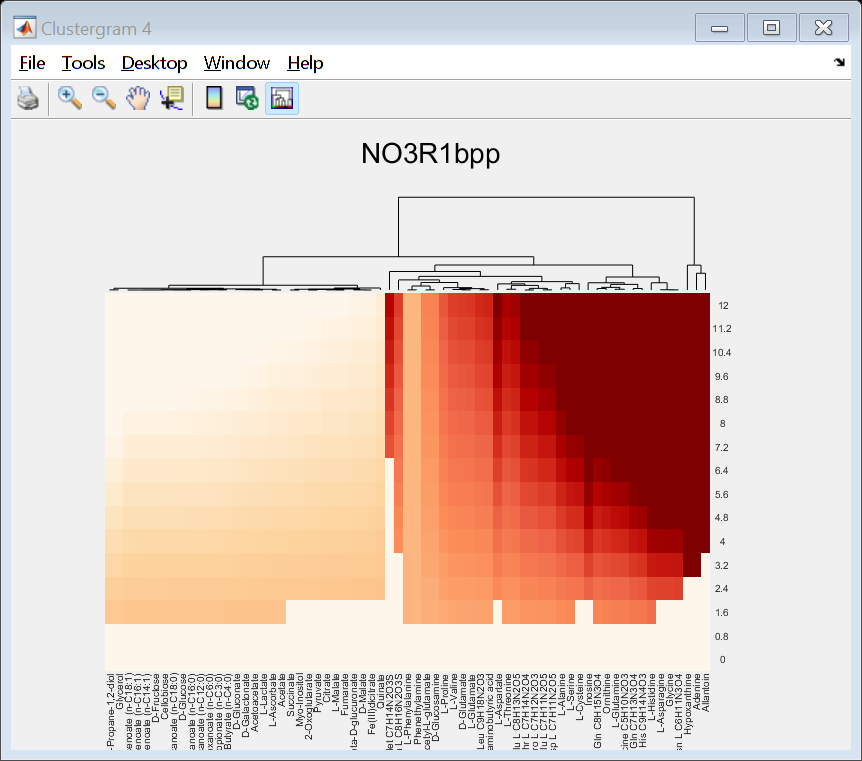

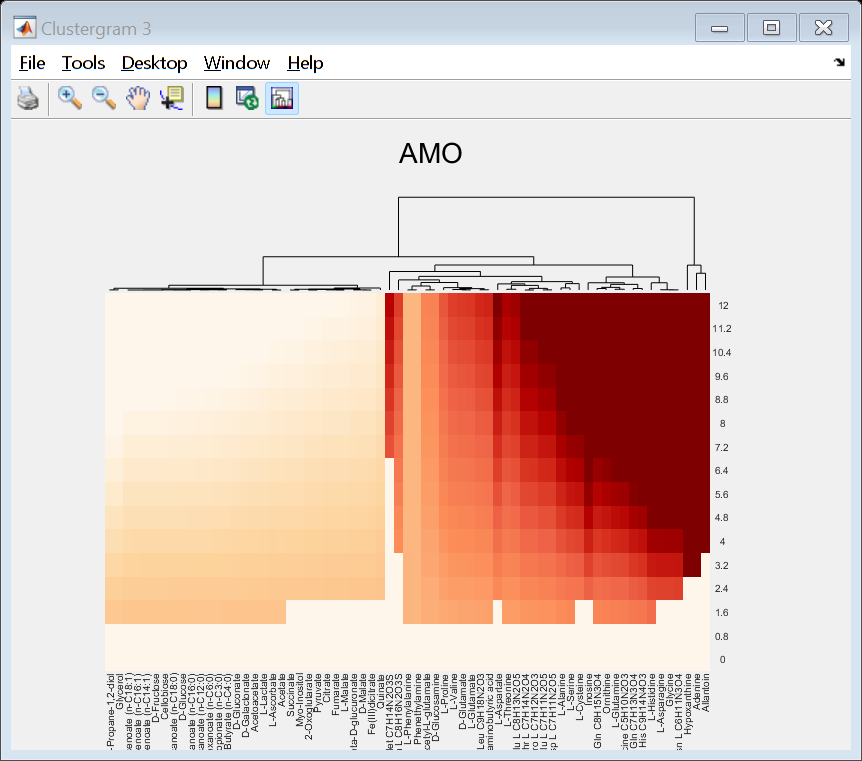

@author : slandarer


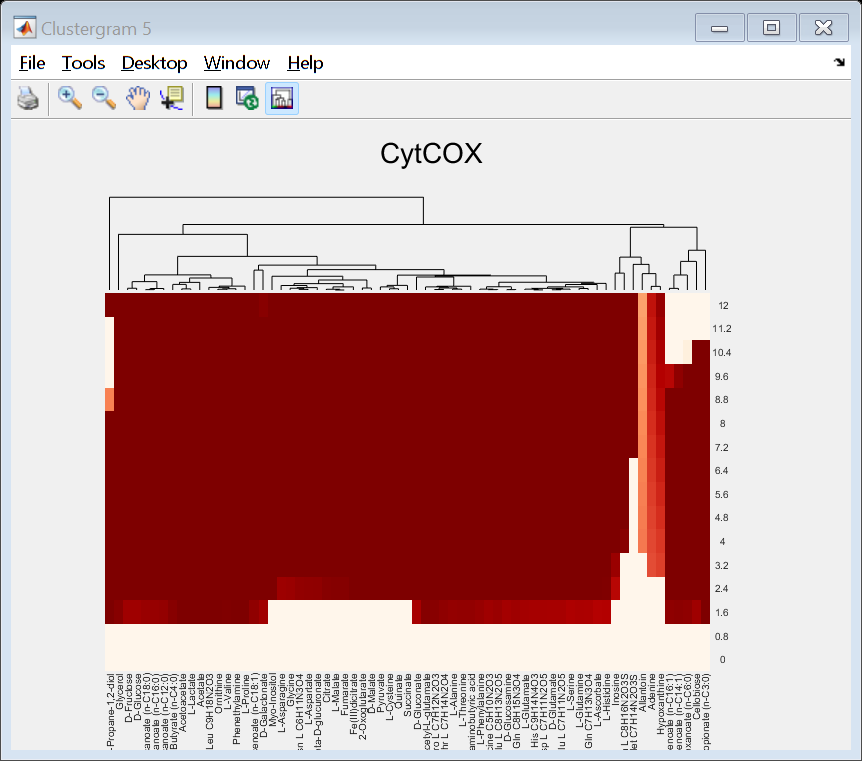

@author : slandarer


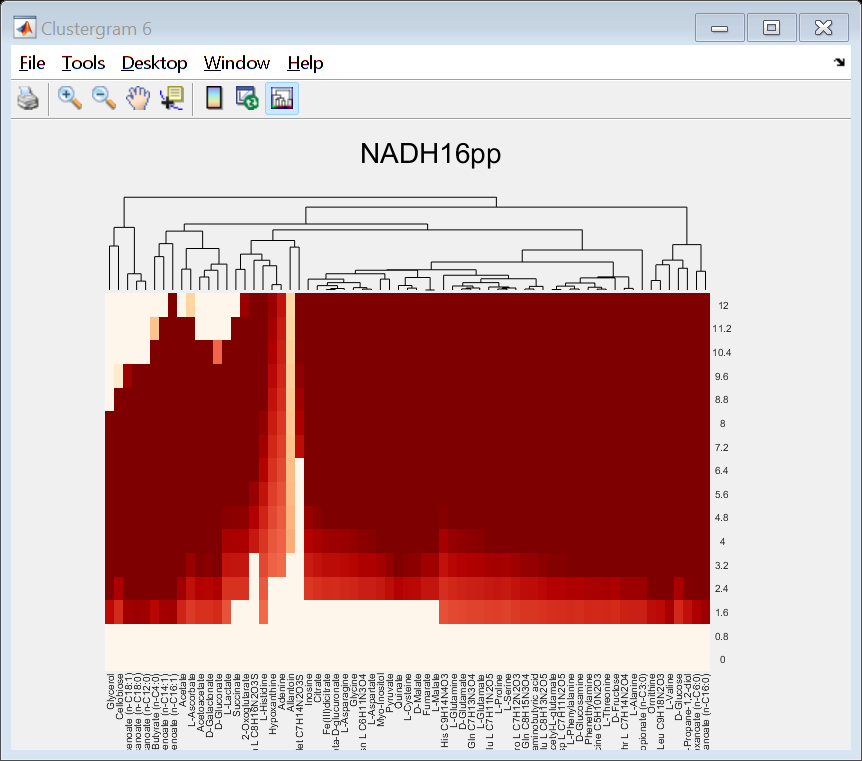

@author : slandarer


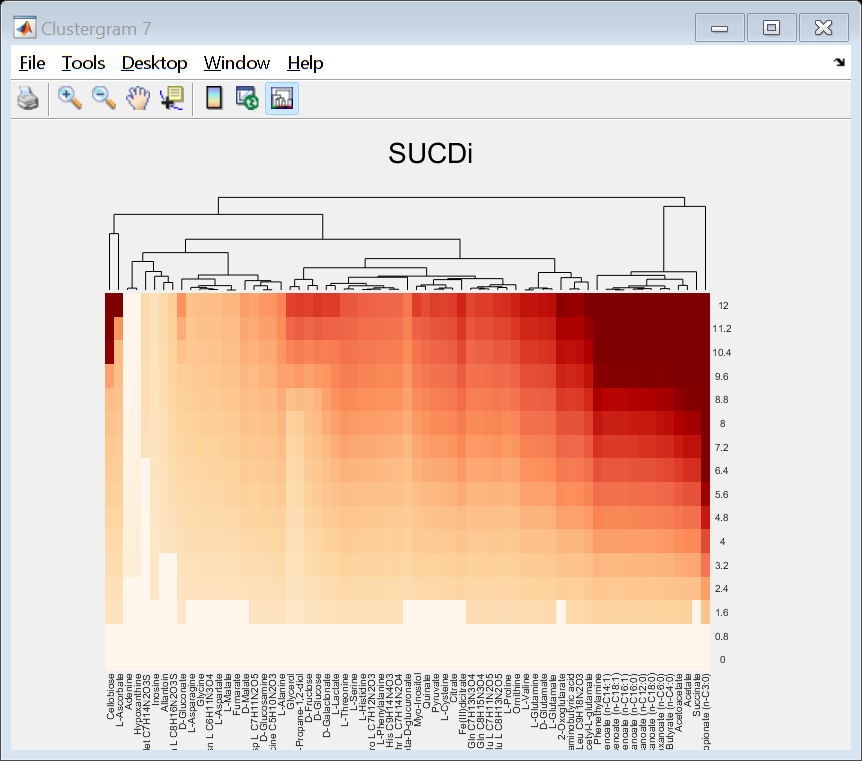

@author : slandarer


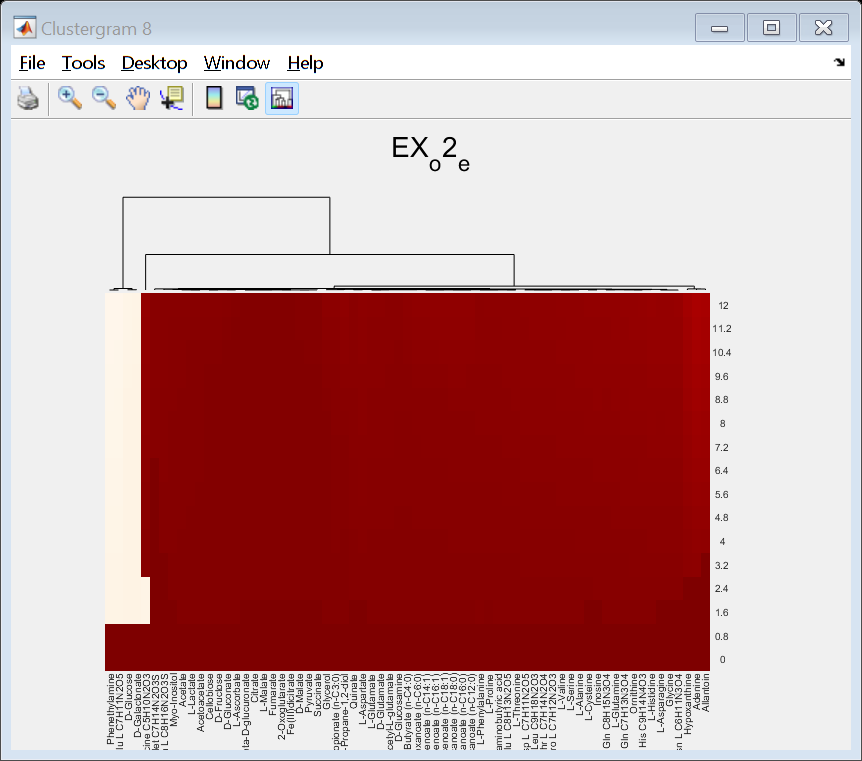

@author : slandarer


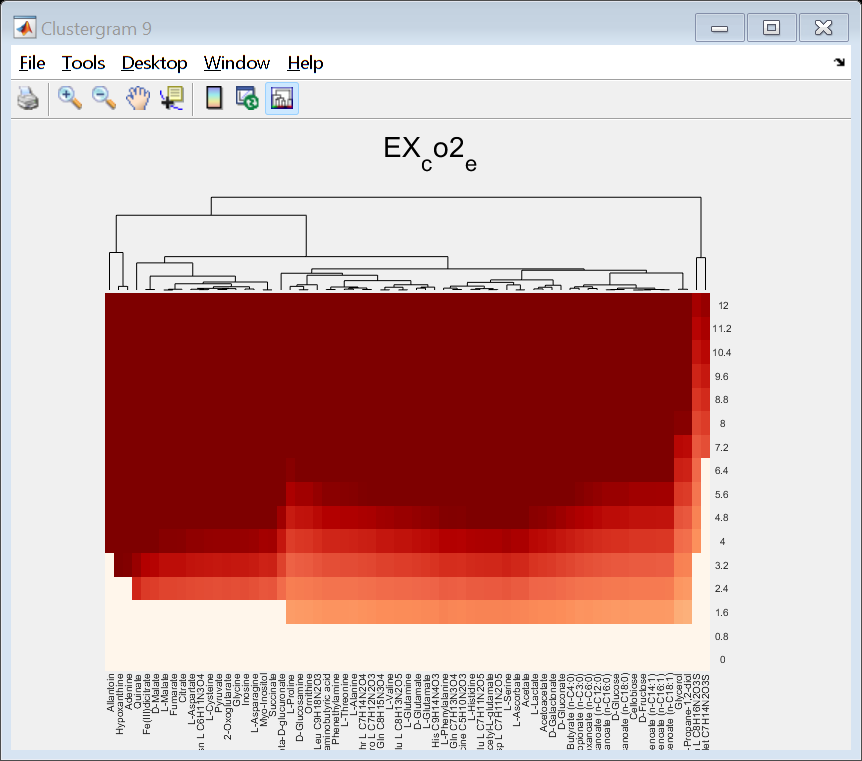

@author : slandarer


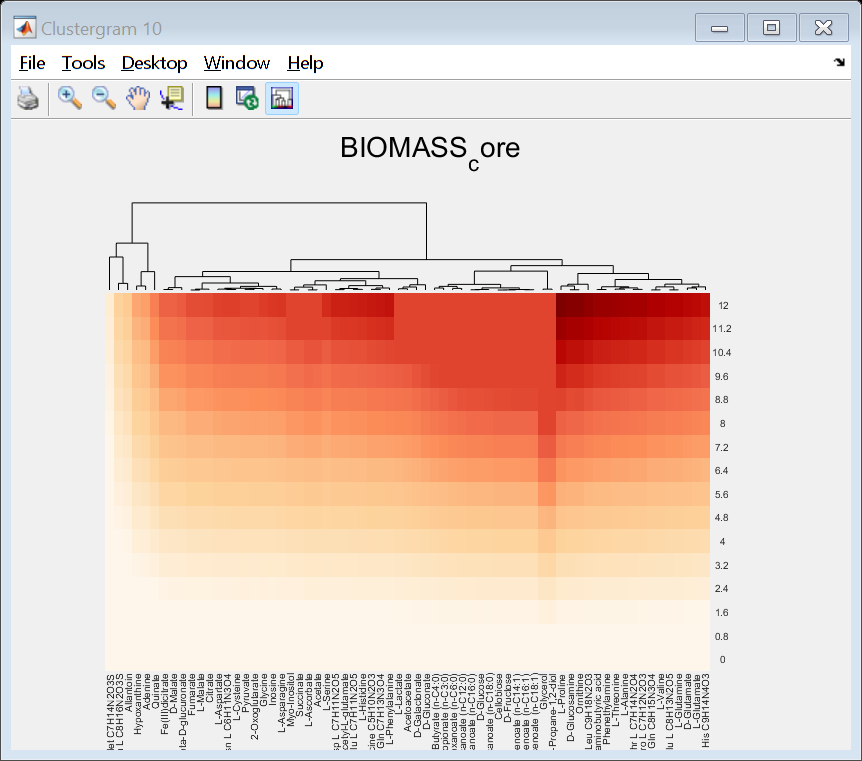


% Using regular FBA
met_names={};
varNames = T.Properties.VariableNames;
for i=1:length(varNames)
    rxn=varNames{i};
    met=findMetsFromRxns(model,rxn);
    met_names(1,i)=model.metNames(findMetIDs(model,met));
end
for j = 1:length(rxnNames)

    rxn = rxnNames{j};
    T   = evalin('base', rxn);

    X = T{:,:};

    h = clustergram( ...
        X, ...
        'Colormap', slanCM('OrRd'), ... 
        'Symmetric', false, ...
        'Cluster', 'row' ...
    );

    h.ColumnLabels = met_names;
    h.RowLabels = 0:0.8:12;
    addTitle(h, rxn);
    if contains(rxnNames{j},'AMO')
       list_cs=h.ColumnLabels;
    end
    
end

## Removing sources that does not trigger nitrification variation

F = AMO;
Fmat = table2array(F);
dF = diff(Fmat, 1, 1);
hasIncrease = any(dF > 0, 1);
hasDecrease = any(dF < 0, 1);
keepCols = hasIncrease & hasDecrease;
F_filtered = F(:, keepCols);
c_names = F_filtered.Properties.VariableNames;


## Plotting heatmaps

@author : slandarer


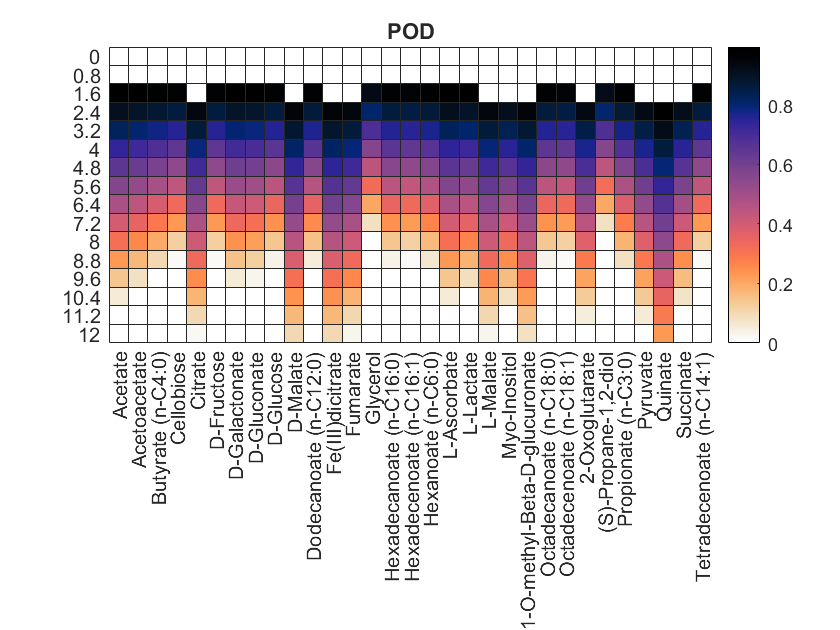

@author : slandarer


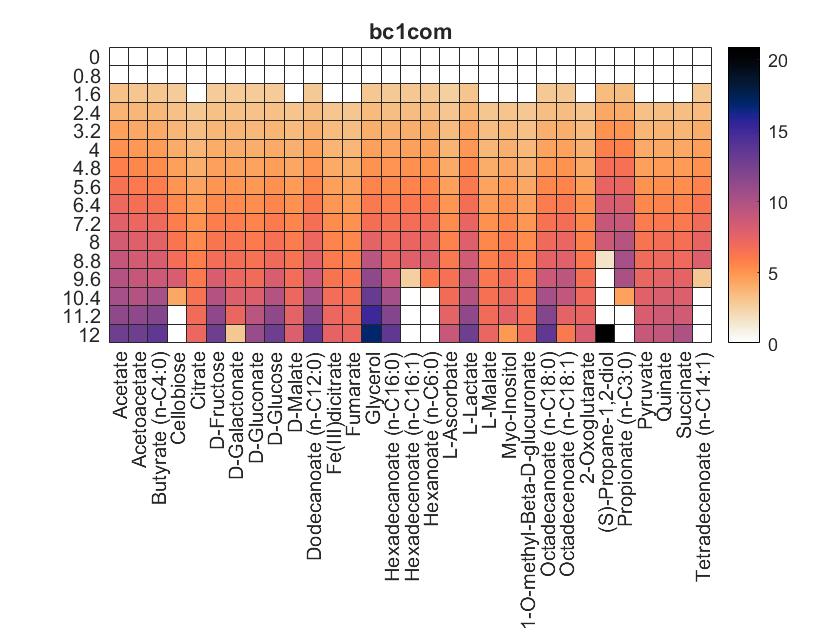

@author : slandarer


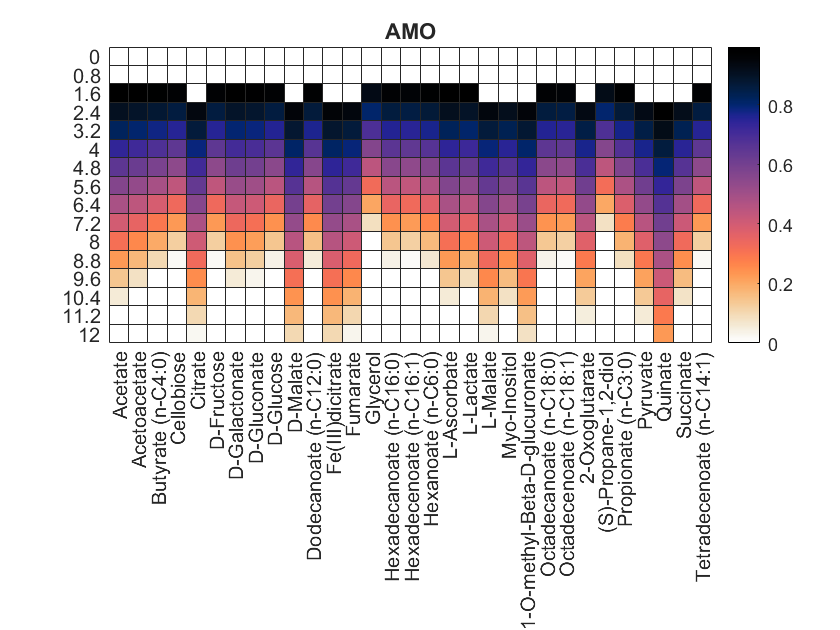

@author : slandarer


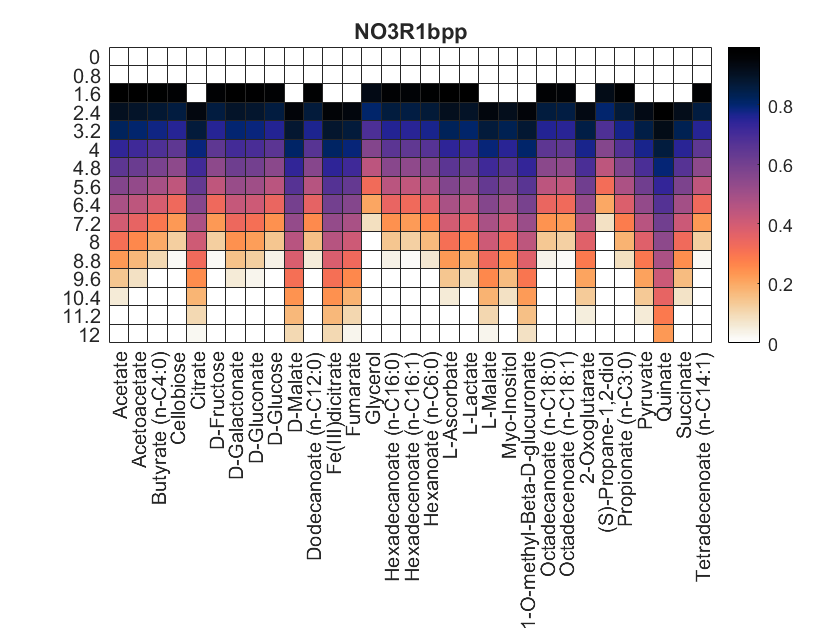

@author : slandarer


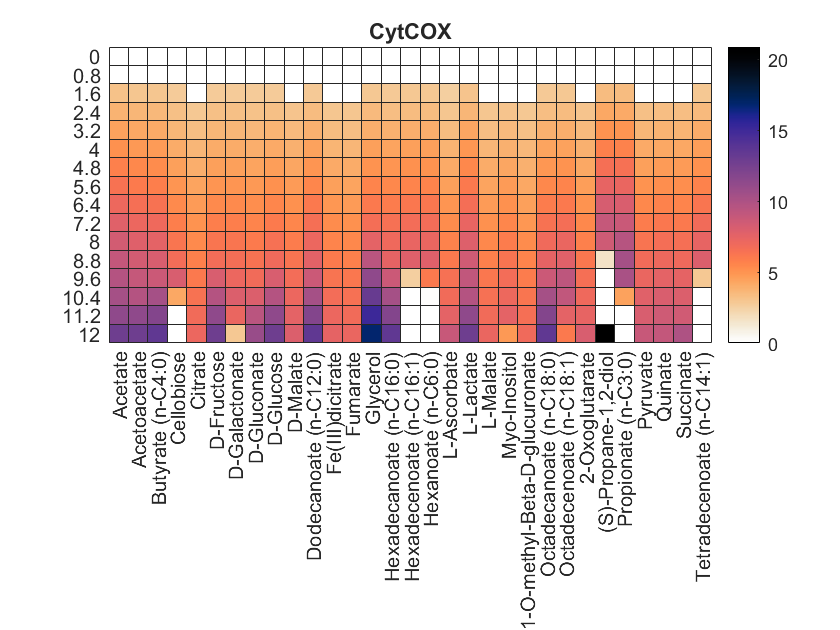

@author : slandarer


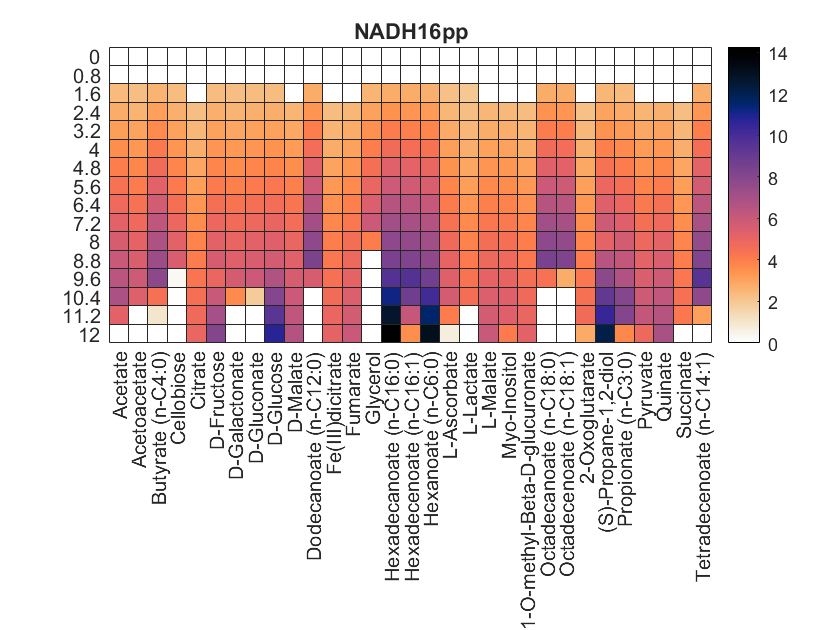

@author : slandarer


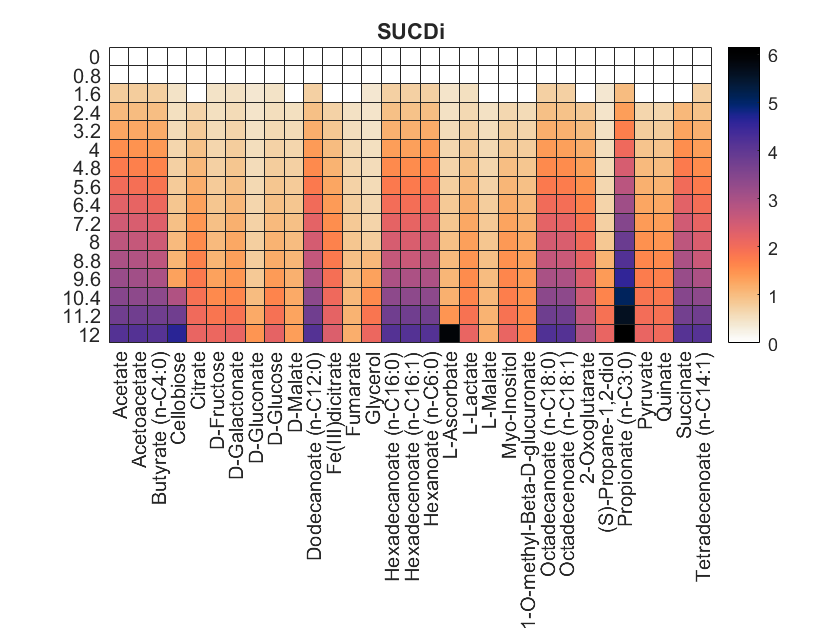

@author : slandarer


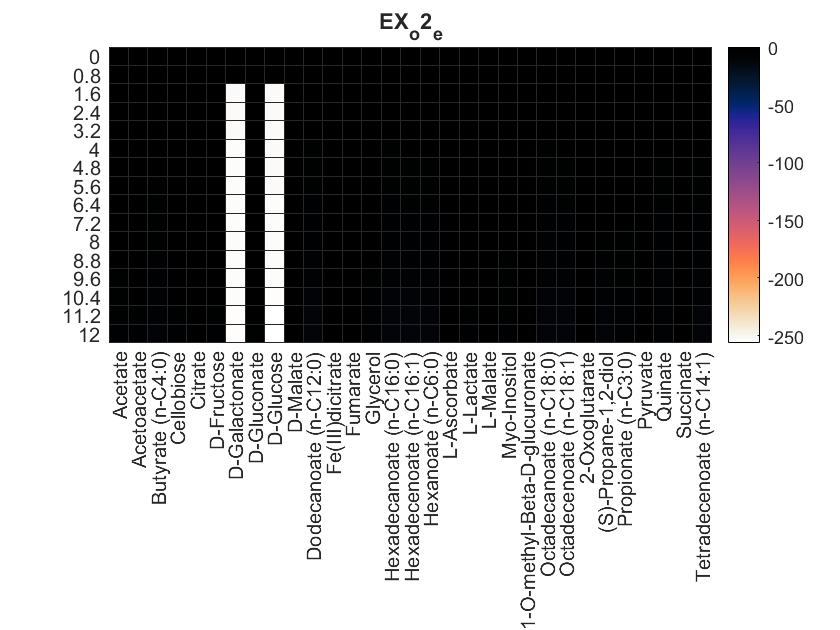

@author : slandarer


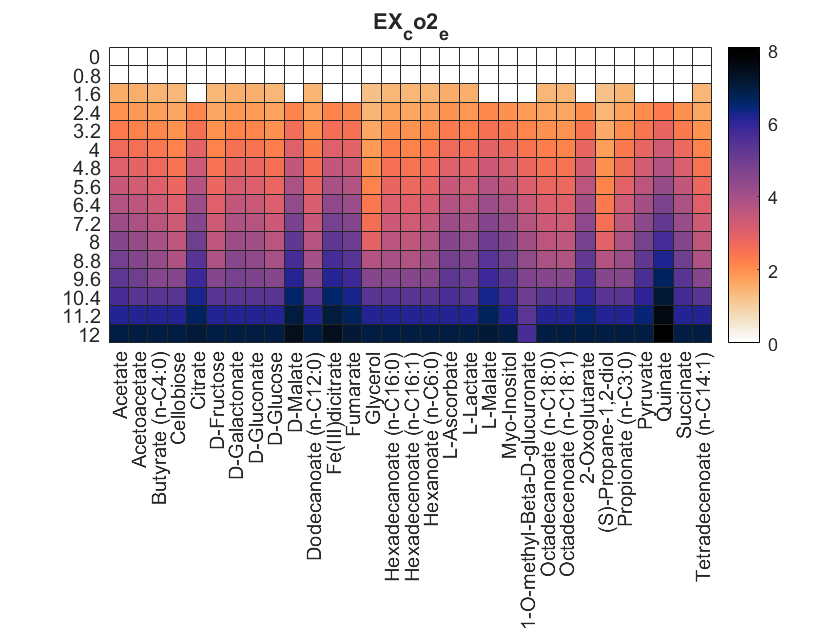

@author : slandarer


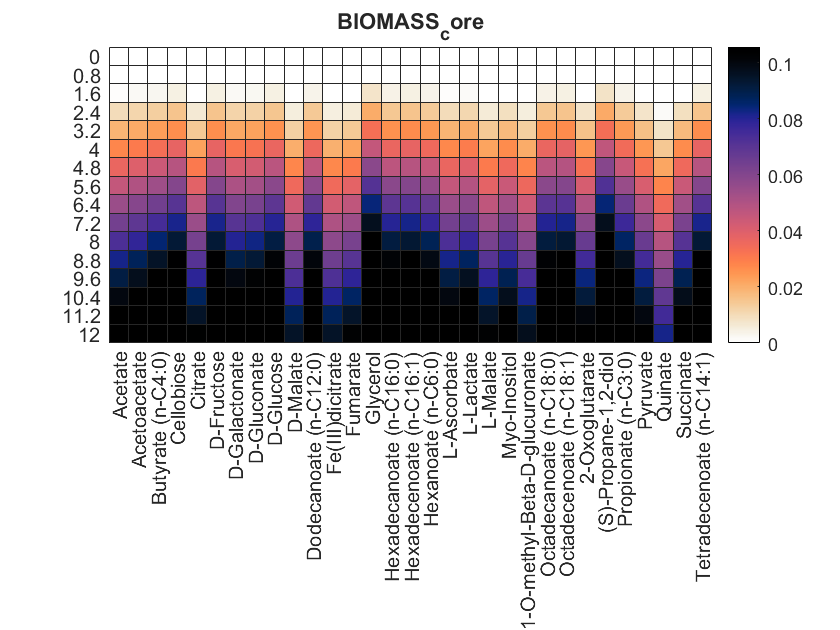

for i = 1:length(rxnNames)
    T_cleaned = table(); 
    F = evalin('base', rxnNames{i});
    T_cleaned = [T_cleaned; F(:, c_names)];
    T_cleaned.EX_phe__L_e = [];
    T_cleaned.EX_peamn_e = [];
    assignin('base', [rxnNames{i},'_filtered'], T_cleaned);

  
    rxnCols = T_cleaned.Properties.VariableNames;
    [tf, rxnIdx] = ismember(rxnCols, model.rxns);

    metLabels = rxnCols;  
    for j = 1:numel(rxnCols)
        if tf(j)
            metIdx = find(model.S(:, rxnIdx(j)) ~= 0, 1); 
            if ~isempty(metIdx)
                metLabels{j} = model.metNames{metIdx};
            end
        end
    end

    sortKey = metLabels;
    for j = 1:numel(metLabels)
        if startsWith(metLabels{j}, '(S)-')
            sortKey{j} = extractAfter(metLabels{j}, '(S)-');
        elseif contains(metLabels{j}, '1-')
            sortKey{j} = extractAfter(metLabels{j}, '1-');
        elseif contains(metLabels{j}, '2-')
            sortKey{j} = extractAfter(metLabels{j}, '2-');
        end
    end


    [~, sortIdx] = sort(lower(sortKey));
    metLabelsSorted = metLabels(sortIdx);
    T_cleaned = T_cleaned(:, sortIdx);

    figure
    h = heatmap(T_cleaned{:,:});
    h.Colormap = flipud(slanCM('torch'));
    h.XDisplayLabels = metLabelsSorted;  
    h.YDisplayLabels = lbs';
    h.Title = rxnNames{i};
end

load('iGC1310');
model = iGC1310;
met_A='EX_nh4_e';
met_B='EX_succ_e';
met_C='AMO';

lb_A=1;
initF_B=0;
inter_B=0.8;
finalF_B=12;
X2=[];
Y2=[];
Z2=[];

for i=0:0.5:4
    lb_nh4=i;
    [X,Y,Z]=gettingFluxData(model,met_A,met_B,met_C,lb_nh4,initF_B,inter_B,finalF_B);
    X2=vertcat(X2,X);
    Y2=vertcat(Y2,Y);
    Z2=vertcat(Z2,Z);
end

figure
h=pcolor(X2,Y2,Z2)

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [9×16 double]
           YData: [9×16 double]
           ZData: [9×16 double]
           CData: [9×16 double]

  Show all properties

colormap(slanCM('parula'))

@author : slandarer


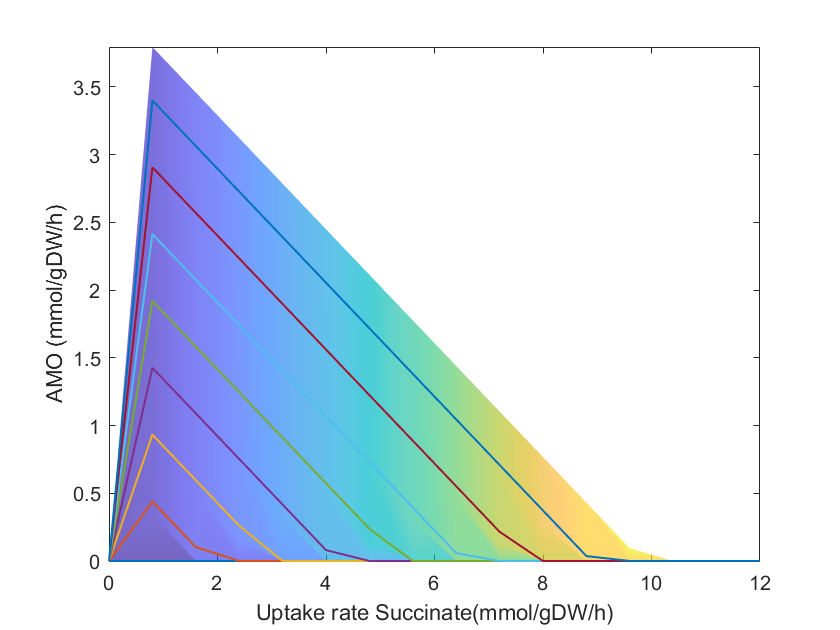

shading interp
h.FaceAlpha = 0.7;
xlabel('Uptake rate Succinate(mmol/gDW/h)');
ylabel('AMO (mmol/gDW/h)')
hold on

for i=0.1:0.5:4
    lb_nh4=i;
    [X,Y,~]=gettingFluxData(model,met_A,met_B,met_C,lb_nh4,initF_B,inter_B,finalF_B);
    plot(X,Y,'LineWidth', 1)
end